# SeaFreeze

V1.0 (Matlab version)

The SeaFreeze package allows to compute the thermodynamic and elastic properties of water and ice polymorphs (Ih, III, V and VI) in the  0-2300 MPa and 220-500K range. It is based on the evaluation of Local  Basis Functions for each phase. The formalism is described in more  details in Brown (2018), Journaux et al. (2019), and in the liquid water Gibbs parametrization by Bollengier, Brown, and Shaw (2019).

## Getting Started

**Prerequisites**

This Matlab version of SeaFreeze has been tested on MATLAB_R2018a.  SeaFreeze does not need any other toolboxes to work. Nonetheless, the  "Curve Fitting Toolbox" allows to run the code significantly faster when evaluating a list of points rather than a grid.

**Installing**

To run SeaFreeze, you can either have it in your active directory or add the SeaFreeze directory added to your path.

## Running SeaFreeze

**Inputs**

To run the SeaFreeze function you need to provide pressure (MPa) and temperature (K) coordinates and a material input:

` > out=SeaFreeze(PT,'material')`

PT is a structure (gridded output) or array (scatter output) containing pressure-temperature points (MPa and Kelvin).

'material' defines which ice or water to use.  Possibilities:

- 'Ih' for ice Ih (Feistel and Wagner, 2006)

- 'III' for ice III (Journaux et al. 2019)

- 'V' for ice V (Journaux et al. 2019)

- 'VI' for ice VI (Journaux et al. 2019)

- 'water1' for Bollengier et al. (2019) LBF extending to 500 K and 2300 MPa

- 'water2' for the modified EOS in Brown 2018 extending to 100 GPa

- 'water_IAPWS95' for IAPWS95 water (Wagner and Pruss, 2002)

**Outputs**

out is a structure containing all output quantities (SI units):

- G (J/kg) Gibbs Energy

- S (J/K/kg) Entropy

- U (J/kg) Internal Energy

- H (J/kg) Enthalpy

- rho(kg/m^3) Density

- Cp (J/kg/K) Specific heat capacity at constant pressure

- Cv (J/kg/K) Specific heat capacity at constant volume

- Kt (MPa) Isothermal bulk modulus

- Kp (dimensionless) Pressure derivative of the Isothermal bulk modulus

- Ks (MPa) Isoentropic bulk modulus

- alpha (/K)  Thermal expansivity

- shear (MPa) Shear modulus

- Vp (m/s) P wave velocity

- Vs (m/s) S wave velocity

- vel (m/s) bulk sound speed

NaN values returned when out of parametrization boundaries.

# Example

## **Single point input**

Single point for ice VI at 900 MPa and 255 K. This can be used to check returned thermodynamic properties values.

PT = {900,255};

out = struct with fields:
      rho: 1.3561e+03
       Cp: 2.0054e+03
        G: 7.4677e+05
       Cv: 1.8762e+03
      vel: 3.6759e+03
       Kt: 1.7143e+04
       Ks: 1.8323e+04
       Kp: 6.2751
        S: -1.3827e+03
        U: -2.6951e+05
        H: 8.3090e+04
    alpha: 2.0020e-04
       Vp: 4.5490e+03
       Vs: 2.3207e+03
    shear: 7.3033e+03


out=SeaFreeze(PT,'VI')

## **Grid  input**

Grid of points for ice V every 2 MPa from 400 to 500 MPa and every 0.5 K from 220 to 250 K

PT = {400:2:500,240:0.5:250};
out=SeaFreeze(PT,'V');

`Density surface plot`

surf(PT{1},PT{2},out.rho');

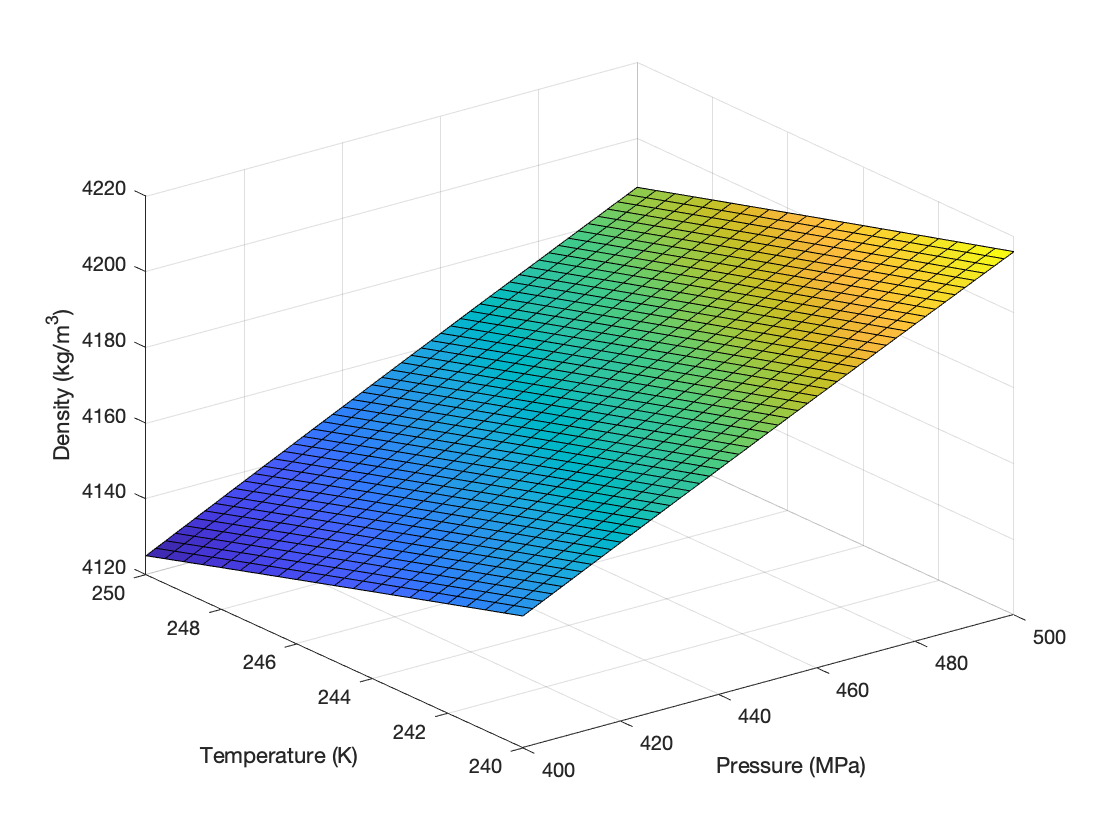

xlabel('Pressure (MPa)')
ylabel('Temperature (K)')
zlabel('Density (kg/m^{3})')

## **List  input**

List of 3 points for liquid water at 300K and 200, 223 and 225 MPa

PT = ([200 300 ; 223 300 ; 225 300 ]);
out=SeaFreeze(PT,'water1')

## **Determine the stable phase**

To determine which phase is stable at a given coordinate, simply use the SF_WhichPhase function. The output number correspond to the stable phase (minimun chemical potential). 

- 0 for liquid water

- 1 for ice Ih

- 3 for ice III

- 5 for ice V

- 6 for ice VI

Here at 600 MPa and 250 K ice V is the stable phase.

SF_WhichPhase({600,250})

ans = 6

## Important remarks

The ices Gibbs parametrizations are optimized to be used with  'water1' Gibbs LBF from Bollengier et al. (2019), specially for phase  equilibrium calculation. Using other water parametrization wil lead to  incorect melting curves. 'water2' (Brown 2018) and 'water_IAPWS95'  (IAPWS95) parametrization are provided for HP extention (up to 100 GPa)  and comparison only. The authors recommend the use of 'water1'  (Bollengier et al. 2019) for any application in the 200-355 K range and  up to 2300 MPa.

## References

- Bollengier, Brown and Shaw (2019) J. Chem. Phys. 151; doi: 10.1063/1.5097179

- Brown (2018) Fluid Phase Equilibria 463, pp. 18-31

- Feistel and Wagner (2006), J. Phys. Chem. Ref. Data 35, pp. 1021-1047

- Journaux et al., (2019) TBD

- Wagner and Pruss (2002), J. Phys. Chem. Ref. Data 31, pp. 387-535

## Authors

- **Baptiste Journaux** - *University of Washington, Earth and Space Sciences Department, Seattle, USA*

- **J. Michael Brown** - *University of Washington, Earth and Space Sciences Department, Seattle, USA*

- **Penny Espinoza** - *University of Washington, Earth and Space Sciences Department, Seattle, USA*

## License

This project is licensed under the MIT License :

Copyright (c) 2019, B. Journaux

Permission is hereby granted, free of charge, to any person obtaining a copy of this software and associated documentation files, to deal in the Software without restriction, including without limitation the rights to use, copy, modify, merge, publish, distribute, sublicense, and/or sell copies of the Software, and to permit persons to whom the Software is furnished to do so, subject to the following conditions:

The above copyright notice and this permission notice shall be included in all copies or substantial portions of the Software.

THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY, FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM, OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE SOFTWARE.

## Acknowledgments

This work was produced with the financial support provided by the  NASA Postdoctoral Program fellowship, by the NASA Solar System Workings  Grant 80NSSC17K0775 and by the Icy Worlds node of NASA's Astrobiology  Institute (08-NAI5-0021).